# Temperatura - Clustering Manuale

I sensori contrassegnati da una croce rossa sono stati eliminati perché non affidabili:

5, 15, 18, 26, 28, 47, 48, 49, 50, 51, 52, 53 e 54 (con la vecchia notazione).

Purtroppo, eliminando delle righe, i sensori vengono "rinominati":

sensori dal 6 al 14: num_riga - 1

sensori dal 16 al 17: num_riga - 2

sensori dal 19 al 25: num_riga - 3

sensore 27: num_riga - 4

sensori dal 29 in poi: num_riga - 5

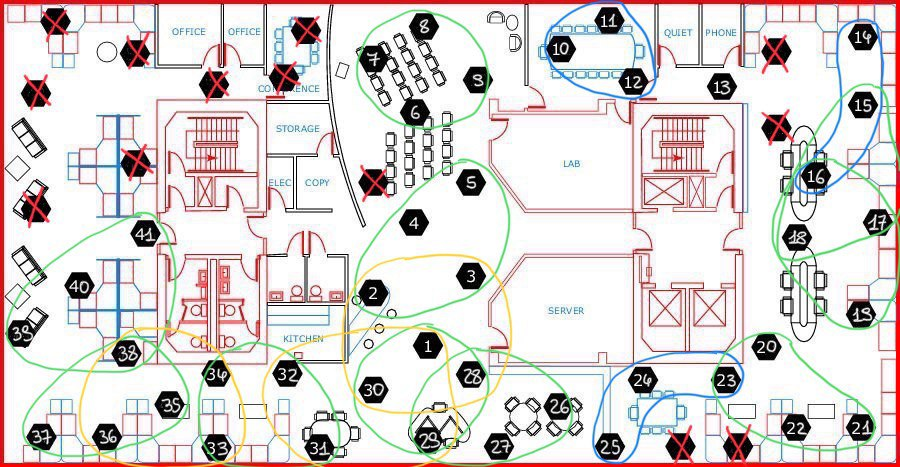

% Carica tutti i dati
load Data.mat

% Numero sensori
num_sensori = 46;

% Variabile: temperatura
j=1; 

% Prende tutti i sensori da 1 a 46
for i=1:num_sensori
  
    % Trova le righe di Data che abbiano i come valore della seconda colonna
    S{i}=find(Data(:,2)==i); % cell array, contiene gli indici delle righe 
    x{i,j}=Data(S{i},j+2); % i-esimo sensore, prima variabile (temperatura)

    % Filtraggio e interpolazione dati
    
    % Identifica gli outliers
    detect_x{i,j} = isoutlier(x{i,j});

    % Rimuove gli outliers
    x{i,j}= rmoutliers(x{i,j});  
    
    % Prende le epoch temporali dalla prima riga di Data (dell'i-esimo sensore)
    t{i,j}=Data(S{i},1);
   
    % Toglie quelle che corrispondono agli outliers
    t{i,j}=t{i,j}(~detect_x{i,j});
    
    % Toglie i doppioni
    [tu{i,j},IA,IC] = unique(t{i,j});
   
    % Prende i corrispettivi valori della variabile in base alle epoch
    xu{i,j}=x{i,j}(IA);

    % Interpola i valori della variabile con la risoluzione voluta
    xint{i,j} = interp1(tu{i,j}, xu{i,j}, [1:10:6e4]);
end

% Elenco dei sensori da escludere
sensori_da_escludere = [5 15 18 26 28];

% controllo: size(xint{1, 1})

% Numero di punti temporali
num_punti_temporali = length(xint{1, 1});  % Lunghezza del primo vettore colonna (variabile temperatura)
                                           % del primo sensore (è uguale per tutti)

% Prealloca la matrice (nulla) per contenere le misure della prima colonna di ciascun sensore

% Riduciamo il numero di righe in base ai sensori da escludere
num_sensori_inclusi = num_sensori - length(sensori_da_escludere);
matrice_misure = zeros(num_sensori_inclusi, num_punti_temporali);

% Indice per le righe della matrice
indice_riga = 1;

% Ciclo su ciascun sensore per estrarre i dati della prima colonna
for k = 1:num_sensori
    % Controlla se il sensore è nella lista da escludere
    if ismember(k, sensori_da_escludere)
        continue;  % Salta al prossimo sensore se è da escludere
    end

    % Estrai la prima variabile (temperatura) del sensore k
    vettore_riga = xint{k, 1}(1, :);

    % Inserisci il vettore riga nella riga corrispondente della matrice
    matrice_misure(indice_riga, :) = vettore_riga;

    % Incrementa l'indice della riga
    indice_riga = indice_riga + 1;
end

# Eliminazione valori NaN tramite sostituzione con il valore medio della serie temporale + calcolo varianza

% Inizializzazione degli array per le medie e le varianze
medie = zeros(41, 1);
varianze = zeros(41, 1);
dev_stand = zeros(41, 1);

% Calcolo della media e della varianza per ogni riga
for l = 1:num_sensori_inclusi
    medie(l) = mean(matrice_misure(l, :), 'omitnan');  % Calcola la media ignorando NaN
    varianze(l) = var(matrice_misure(l, :), 'omitnan'); % Calcola la varianza ignorando NaN
    dev_stand(l) = sqrt(varianze(l));
end

for k = 1:num_sensori_inclusi % Ciclo attraverso ogni sensore
    for l = 1:num_punti_temporali % Ciclo attraverso ogni punto temporale
        if isnan(matrice_misure(k, l)) % Controlla se il valore è NaN
            matrice_misure(k,l) = medie(k,1);  % Sostituisce NaN con la media del sensore           
        end
    end
end

## Si ipotizza che il sensore x sia guasto per un certo intervallo di tempo e si ricostruisce il suo segnale misura a partire dal segnale media dei sensori appartenenti ai vari tipi di clustering (di cui il sensore in questione fa parte)

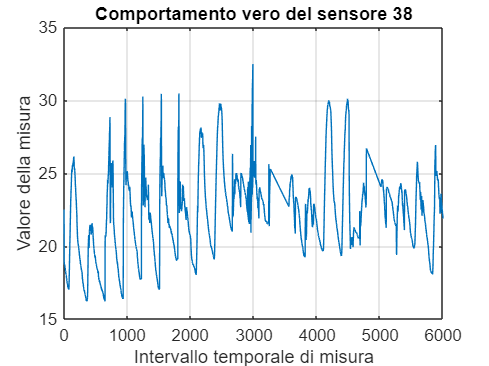

% Ipotesi sensore guasto n.:
sensore_x = 38;

% Ipotesi intervallo temporale di misura del guasto:
colonne_corrispondenti = 1:6000;

% Estrae la riga del sensore_x e le colonne dell'intervallo temporale di misura
dati_riga = matrice_misure(sensore_x, colonne_corrispondenti);

% Plot comportamento vero del sensore_x
figure; % Crea una nuova figura
comp_vero = plot(colonne_corrispondenti, dati_riga);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
title(['Comportamento vero del sensore ' num2str(sensore_x)]);
grid on; % Aggiunge la griglia al grafico

% Matrice raggruppamenti a 3 sensori
matr_raggr3b = [23 24 25;
               10 11 12; 
               14 15 16];

% Matrice raggruppamenti a 4 sensori
matr_raggr4g = [38 39 40 41;
               35 36 37 38;
               31 32 33 34;
               1 28 29 30;
               26 27 28 29;
               2 3 4 5;
               6 7 8 9;
               20 21 22 23;
               16 17 18 19;
               15 16 17 18];

% Matrice raggruppamenti a 5 sensori
matr_raggr5y = [33 34 35 36 38;
               1 29 30 31 32;
               1 2 3 28 30];

% Controlli
% Inizializza il vettore
vettore_flag_raggruppamenti = zeros(1, 3);

% Raggruppamenti a 3 sensori

% Controlla se la matrice contiene almeno un elemento uguale a sensore_x
if any(matr_raggr3b(:) == sensore_x)
    vettore_flag_raggruppamenti(1) = 1;
end

% Raggruppamenti a 4 sensori

% Controlla se la matrice contiene almeno un elemento uguale a sensore_x
if any(matr_raggr4g(:) == sensore_x)
    vettore_flag_raggruppamenti(2) = 1;
end

% Raggruppamenti a 5 sensori

% Controlla se la matrice contiene almeno un elemento uguale a sensore_x
if any(matr_raggr5y(:) == sensore_x)
    vettore_flag_raggruppamenti(3) = 1;
end

# 3 sensori

% Controlla se ci sono raggruppamenti a 3 sensori disponibili
if vettore_flag_raggruppamenti(1) == 1

% i raggruppamenti a 3 stanno nella matrice matr_raggr3b

% Trova le righe che contengono il sensore_x
righe_con_sensore = any(matr_raggr3b == sensore_x, 2); 

% Estrae le righe che contengono il valore sensore_x
matrice_righe_con_sensore = matr_raggr3b(righe_con_sensore, :);

% Inizializza una matrice vuota per memorizzare le righe modificate
matrice_modificata = [];

% Ciclo su ogni riga della matrice
for i = 1:size(matrice_righe_con_sensore, 1)
    % Rimuovi gli elementi uguali al sensore_x dalla riga
    riga_modificata = matrice_righe_con_sensore(i, matrice_righe_con_sensore(i,:) ~= sensore_x);
    
    % Aggiungi la riga modificata alla matrice ridimensionata
    matrice_modificata = [matrice_modificata; riga_modificata];
end

% Numero di righe in matrice_modificata
num_righe = size(matrice_modificata, 1);

% Inizializza la matrice per le medie
matrice_medie = zeros(num_righe, size(matrice_misure, 2));

% Ciclo su ogni riga di matrice_modificata
for i = 1:num_righe
    % Ottieni la riga corrente di matrice_modificata
    riga_modificata = matrice_modificata(i, :);
    
    % Inizializza un array per sommare le misure dei sensori
    media_colonne = zeros(1, size(matrice_misure, 2));
    
    % Ciclo sui sensori nella riga_modificata
    for j = 1:length(riga_modificata)
        % Estrae il sensore corrente dalla riga_modificata
        sensore_corrente = riga_modificata(j);
   1     
        % Estrae le misure del sensore corrente da matrice_misure
        misure_sensore = matrice_misure(sensore_corrente, :);
        
        % Somma le misure del sensore corrente
        media_colonne = media_colonne + misure_sensore;
    end
    
    % Calcola la media per colonna
    media_colonne = media_colonne / length(riga_modificata);
    
    % Salva la media nella matrice delle medie (ogni riga contiene le medie per ogni gruppo)
    matrice_medie(i, :) = media_colonne;
end

num_righe_matrmed = size(matrice_medie,1);
disp(['Il numero di raggruppamenti disponibili (3) è: ', num2str(num_righe_matrmed)]);

% Mostra il numero di raggruppamenti disponibili
disp(['Puoi scegliere un raggruppamento tra 1 e ', num2str(num_righe_matrmed),'.']);

% Richiedi all'utente di scegliere il numero di raggruppamento
raggruppamento = input(['Inserisci il numero del raggruppamento (3) di tuo interesse (1-', num2str(num_righe_matrmed), '): ']);

% Verifica se il numero inserito è valido
if raggruppamento >= 1 && raggruppamento <= num_righe_matrmed
    disp(['Hai scelto il raggruppamento n.:', num2str(raggruppamento)]);

    figure;
    hold on;

    % Plot del comportamento vero
    comp_vero = plot(colonne_corrispondenti, dati_riga(colonne_corrispondenti), 'DisplayName', 'VERO');

    % Plot del comportamento stimato con il raggruppamento scelto
    comp_k = plot(colonne_corrispondenti, matrice_medie(raggruppamento, colonne_corrispondenti), 'DisplayName', ['MANUALE 3R n. ', num2str(raggruppamento)]);

    xlabel('Intervallo temporale di misura');
    ylabel('Valore della misura');
    legend show;
    title('Grafico combinato');
    grid on; % Aggiunge la griglia al grafico
    hold off;

# Residui messi a confronto // Cross-Error function

## Definita come la differenza tra l’uscita/misura osservata (ỹ_x) e quella stimata (ŷ_x) nello stesso istante temporale.

% misura osservata è contenuta nel vettore dati_riga
% misura stimata è contenuta in dati_rigak
dati_rigam = matrice_medie(raggruppamento, colonne_corrispondenti);

cef_m = dati_riga - dati_rigam;

% Calcolare l'errore quadratico medio
errore_quadratico_mediom = sqrt(mean((cef_m).^2));

% Visualizzare il risultato
disp(['L''errore quadratico medio (RMSE) per MANUAL 3R è: ', num2str(errore_quadratico_mediom)]);

figure; % Crea una nuova figura
hold on;
plot(colonne_corrispondenti, cef_m);

xlabel('Intervallo temporale di misura');
ylabel('Valore della cross-error function');
legend('MANUAL 3R');
title('Cross-error functions');
grid on; % Aggiunge la griglia al grafico
hold off;

clf; % Pulisce la finestra grafica
    else
    disp('Il numero inserito non è valido. Riprova.');
end
else
    disp('Non ci sono raggruppamenti a 3 sensori disponibili.');
end

Non ci sono raggruppamenti a 3 sensori disponibili.


# 4 sensori

% Controlla se ci sono raggruppamenti a 4 sensori disponibili
if vettore_flag_raggruppamenti(2) == 1

% i raggruppamenti a 4 stanno nella matrice matr_raggr4g

% Trova le righe che contengono il sensore_x
righe_con_sensore = any(matr_raggr4g == sensore_x, 2); 

% Estrae le righe che contengono il valore sensore_x
matrice_righe_con_sensore = matr_raggr4g(righe_con_sensore, :);

% Inizializza una matrice vuota per memorizzare le righe modificate
matrice_modificata = [];

% Ciclo su ogni riga della matrice
for i = 1:size(matrice_righe_con_sensore, 1)
    % Rimuovi gli elementi uguali al sensore_x dalla riga
    riga_modificata = matrice_righe_con_sensore(i, matrice_righe_con_sensore(i,:) ~= sensore_x);
    
    % Aggiungi la riga modificata alla matrice ridimensionata
    matrice_modificata = [matrice_modificata; riga_modificata];
end

% Numero di righe in matrice_modificata
num_righe = size(matrice_modificata, 1);

% Inizializza la matrice per le medie
matrice_medie = zeros(num_righe, size(matrice_misure, 2));

% Ciclo su ogni riga di matrice_modificata
for i = 1:num_righe
    % Ottieni la riga corrente di matrice_modificata
    riga_modificata = matrice_modificata(i, :);
    
    % Inizializza un array per sommare le misure dei sensori
    media_colonne = zeros(1, size(matrice_misure, 2));
    
    % Ciclo sui sensori nella riga_modificata
    for j = 1:length(riga_modificata)
        % Estrae il sensore corrente dalla riga_modificata
        sensore_corrente = riga_modificata(j);
        
        % Estrae le misure del sensore corrente da matrice_misure
        misure_sensore = matrice_misure(sensore_corrente, :);
        
        % Somma le misure del sensore corrente
        media_colonne = media_colonne + misure_sensore;
    end
    
    % Calcola la media per colonna
    media_colonne = media_colonne / length(riga_modificata);
    
    % Salva la media nella matrice delle medie (ogni riga contiene le medie per ogni gruppo)
    matrice_medie(i, :) = media_colonne;
end

num_righe_matrmed = size(matrice_medie,1);
disp(['Il numero di raggruppamenti disponibili (4) è: ', num2str(num_righe_matrmed)]);

% Mostra il numero di raggruppamenti disponibili
disp(['Puoi scegliere un raggruppamento tra 1 e ', num2str(num_righe_matrmed),'.']);

% Richiedi all'utente di scegliere il numero di raggruppamento
raggruppamento = input(['Inserisci il numero del raggruppamento (4) di tuo interesse (1-', num2str(num_righe_matrmed), '): ']);

% Verifica se il numero inserito è valido
if raggruppamento >= 1 && raggruppamento <= num_righe_matrmed
    disp(['Hai scelto il raggruppamento n.:', num2str(raggruppamento)]);

    figure;
    hold on;

    % Plot del comportamento vero
    comp_vero = plot(colonne_corrispondenti, dati_riga(colonne_corrispondenti), 'DisplayName', 'VERO');

    % Plot del comportamento stimato con il raggruppmento scelto
    comp_k = plot(colonne_corrispondenti, matrice_medie(raggruppamento, colonne_corrispondenti), 'DisplayName', ['MANUALE 4R n. ', num2str(raggruppamento)]);

    xlabel('Intervallo temporale di misura');
    ylabel('Valore della misura');
    legend show;
    title('Grafico combinato');
    grid on; % Aggiunge la griglia al grafico
    hold off;

# Residui messi a confronto // Cross-Error function

## Definita come la differenza tra l’uscita/misura osservata (ỹ_x) e quella stimata (ŷ_x) nello stesso istante temporale.

Il numero di raggruppamenti disponibili (4) è: 2


Puoi scegliere un raggruppamento tra 1 e 2.


Hai scelto il raggruppamento n.:2


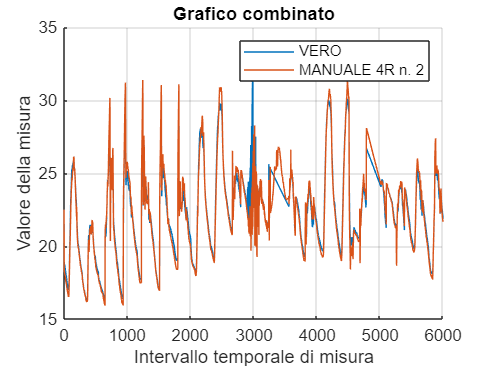

L'errore quadratico medio (RMSE) per MANUAL 4R è: 0.72155


% misura osservata è contenuta nel vettore dati_riga
% misura stimata è contenuta in dati_rigak
dati_rigam = matrice_medie(raggruppamento, colonne_corrispondenti);

cef_m = dati_riga - dati_rigam;

% Calcolare l'errore quadratico medio
errore_quadratico_mediom = sqrt(mean((cef_m).^2));

% Visualizzare il risultato
disp(['L''errore quadratico medio (RMSE) per MANUAL 4R è: ', num2str(errore_quadratico_mediom)]);

figure; % Crea una nuova figura
hold on;
plot(colonne_corrispondenti, cef_m);

xlabel('Intervallo temporale di misura');
ylabel('Valore della cross-error function');
legend('MANUAL 4R');
title('Cross-error functions');
grid on; % Aggiunge la griglia al grafico
hold off;

clf; % Pulisce la finestra grafica
    else
    disp('Il numero inserito non è valido. Riprova.');
end

else
    disp('Non ci sono raggruppamenti a 4 sensori disponibili.');
end

# 5 sensori

% Controlla se ci sono raggruppamenti a 5 sensori disponibili
if vettore_flag_raggruppamenti(3) == 1

% i raggruppamenti a 5 stanno nella matrice matr_raggr5y

% Trova le righe che contengono il sensore_x
righe_con_sensore = any(matr_raggr5y == sensore_x, 2); 

% Estrae le righe che contengono il valore sensore_x
matrice_righe_con_sensore = matr_raggr5y(righe_con_sensore, :);

% Inizializza una matrice vuota per memorizzare le righe modificate
matrice_modificata = [];

% Ciclo su ogni riga della matrice
for i = 1:size(matrice_righe_con_sensore, 1)
    % Rimuovi gli elementi uguali al sensore_x dalla riga
    riga_modificata = matrice_righe_con_sensore(i, matrice_righe_con_sensore(i,:) ~= sensore_x);
    
    % Aggiungi la riga modificata alla matrice ridimensionata
    matrice_modificata = [matrice_modificata; riga_modificata];
end

% Numero di righe in matrice_modificata
num_righe = size(matrice_modificata, 1);

% Inizializza la matrice per le medie
matrice_medie = zeros(num_righe, size(matrice_misure, 2));

% Ciclo su ogni riga di matrice_modificata
for i = 1:num_righe
    % Ottieni la riga corrente di matrice_modificata
    riga_modificata = matrice_modificata(i, :);
    
    % Inizializza un array per sommare le misure dei sensori
    media_colonne = zeros(1, size(matrice_misure, 2));
    
    % Ciclo sui sensori nella riga_modificata
    for j = 1:length(riga_modificata)
        % Estrae il sensore corrente dalla riga_modificata
        sensore_corrente = riga_modificata(j);
        
        % Estrae le misure del sensore corrente da matrice_misure
        misure_sensore = matrice_misure(sensore_corrente, :);
        
        % Somma le misure del sensore corrente
        media_colonne = media_colonne + misure_sensore;
    end
    
    % Calcola la media per colonna
    media_colonne = media_colonne / length(riga_modificata);
    
    % Salva la media nella matrice delle medie (ogni riga contiene le medie per ogni gruppo)
    matrice_medie(i, :) = media_colonne;
end

num_righe_matrmed = size(matrice_medie,1);
disp(['Il numero di raggruppamenti disponibili (5) è: ', num2str(num_righe_matrmed)]);

% Mostra il numero di raggruppamenti disponibili
disp(['Puoi scegliere un raggruppamento tra 1 e ', num2str(num_righe_matrmed),'.']);

% Richiedi all'utente di scegliere il numero di raggruppamento
raggruppamento = input(['Inserisci il numero del raggruppamento (5) di tuo interesse (1-', num2str(num_righe_matrmed), '): ']);

% Verifica se il numero inserito è valido
if raggruppamento >= 1 && raggruppamento <= num_righe_matrmed
    disp(['Hai scelto il raggruppamento n.:', num2str(raggruppamento)]);

    figure;
    hold on;

    % Plot del comportamento vero
    comp_vero = plot(colonne_corrispondenti, dati_riga(colonne_corrispondenti), 'DisplayName', 'VERO');

    % Plot del comportamento stimato con il gruppo scelto
    comp_k = plot(colonne_corrispondenti, matrice_medie(raggruppamento, colonne_corrispondenti), 'DisplayName', ['MANUALE 5R n. ', num2str(raggruppamento)]);

    xlabel('Intervallo temporale di misura');
    ylabel('Valore della misura');
    legend show;
    title('Grafico combinato');
    grid on; % Aggiunge la griglia al grafico
    hold off;

# Residui messi a confronto // Cross-Error function

## Definita come la differenza tra l’uscita/misura osservata (ỹ_x) e quella stimata (ŷ_x) nello stesso istante temporale.

Il numero di raggruppamenti disponibili (5) è: 1


Puoi scegliere un raggruppamento tra 1 e 1.


Hai scelto il raggruppamento n.:1


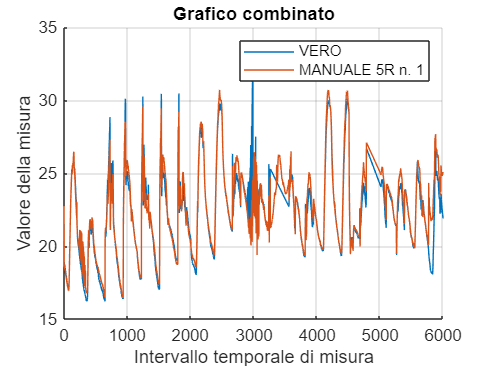

L'errore quadratico medio (RMSE) per MANUAL 5R è: 0.95534


% misura osservata è contenuta nel vettore dati_riga
% misura stimata è contenuta in dati_rigak
dati_rigam = matrice_medie(raggruppamento, colonne_corrispondenti);

cef_m = dati_riga - dati_rigam;

% Calcolare l'errore quadratico medio
errore_quadratico_mediom = sqrt(mean((cef_m).^2));

% Visualizzare il risultato
disp(['L''errore quadratico medio (RMSE) per MANUAL 5R è: ', num2str(errore_quadratico_mediom)]);

figure; % Crea una nuova figura
hold on;
plot(colonne_corrispondenti, cef_m);

xlabel('Intervallo temporale di misura');
ylabel('Valore della cross-error function');
legend('MANUAL 5R');
title('Cross-error functions');
grid on; % Aggiunge la griglia al grafico
hold off;

clf; % Pulisce la finestra grafica
    else
    disp('Il numero inserito non è valido. Riprova.');
end

else
    disp('Non ci sono raggruppamenti a 5 sensori disponibili.');
end